# Biomedical Signal & Image Processing

**Session 1**

@Autors 

Roham Kaveie - Ehsan Merikhi

## EMG Section

part 1) First, we plot the EMG signal of all three subjects and compare their characteristics in the time domain.

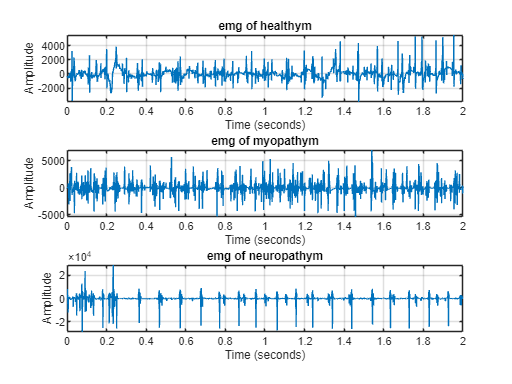

load("EMG_sig.mat")
L = length(emg_healthym);
emg_signals = [emg_healthym;emg_myopathym(1:L);emg_neuropathym(1:L)];

emg_name = ["emg of healthym","emg of myopathym","emg of neuropathym"];
% Plotting the signal

figure;                % Create a new figure
for i = 1:length(emg_name)
    L = length(emg_signals(i,:));
    time = [1:L]/fs;
    subplot(3,1,i);
    plot(time,emg_signals(i,:));
    title(emg_name(i));
    xlabel('Time (seconds)');   % X-axis label
    ylabel('Amplitude');         % Y-axis label
    xlim([0 2]);
    grid on;
    
end

By comparing the signals, we can see that in myopathy, the EMG signal has more fluctuations in shorter periods than in a healthy person. Also, the range of these fluctuations is less.

Also, in the patient with neuropathy, the amplitude of the EMG signal is more but cut and there are many fluctuations but with a greater distance from each other.

part 2) We plot the frequency spectrum and the time-frequency spectrum of all three signals and compare them.

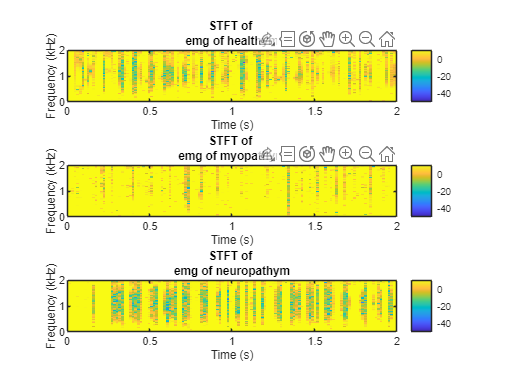

load("EMG_sig.mat")
L = length(emg_healthym);
emg_signals = [emg_healthym;emg_myopathym(1:L);emg_neuropathym(1:L)];

emg_name = ["emg of healthym","emg of myopathym","emg of neuropathym"];
% Plotting the signal



figure;
for i = 1:length(emg_name)
    
    L = length(emg_signals(i,:));
    time = [1:L]/fs;
    subplot(3,1,i);
    window_length = 128;
    noverlap = 64;
    nfft = 128;
    window = hamming(window_length);
    spectrogram(emg_signals(i,:), window, noverlap, nfft, fs, 'yaxis');
    title(['STFT of ' emg_name(i)]);
    ylim([0 2]);
    xlim([0 2]);
    colorbar;
    caxis([-50 10]);  % Adjust this range for better contrast if needed    
end

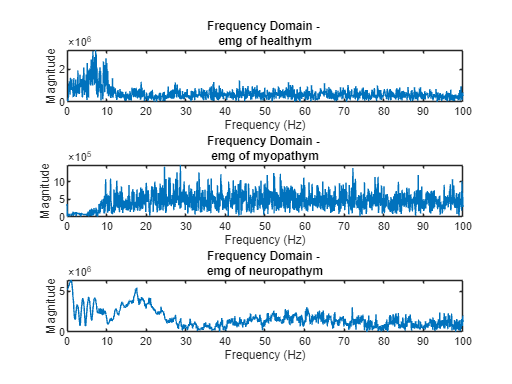


figure;

for i = 1:length(emg_name)
    
    L = length(emg_signals(i,:));
    time = [1:L]/fs;
    subplot(3,1,i);

    % Frequency domain using FFT (DFT)
    N = length(emg_signals(i,:));  % Length of the signal
    f = (0:N-1)*(fs/N);  % Frequency vector
    
    % FFT of the left eye signal
    fft_resp = abs(fft(emg_signals(i,:)));
    
    plot(f, fft_resp);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Domain - ' emg_name(i)]);
    xlim([0 100]);  % Limiting to 60 Hz for better visualization
end

The frequency response and the frequency-time spectrum also show the differences that were mentioned in section 1 about the three signals.

part 3) A summary of the research conducted on the difference in the EMG signal in a healthy person and people with neuropathy and myopathy is given below.

## Myopathic EMG

In myopathy, the abnormality in the EMG signal is caused by the smallness of the motor units in the muscle, which results in large fluctuations and a small amplitude of the EMG signal compared to a healthy person.

In myopathic EMG:

- **MUAP Characteristics:**

- Smaller amplitude (typically <1 mV)

- Shorter duration

- Polyphasic waveforms (more turns and phases than normal)

- **Recruitment Pattern:**

- Early recruitment of motor units

- Rapid filling of the interference pattern, even with submaximal effort

- May show abnormal spontaneous activity like fibrillations or positive sharp waves in some myopathies

## Neuropathic EMG    

Neuropathy, or peripheral neuropathy, is a condition that occurs when the nerves outside of the spinal cord and brain are damaged, causing them to stop working properly.

In neuropathic EMG:

- **MUAP Characteristics:**

- Larger amplitude

- Longer duration

- Often polyphasic

- **Recruitment Pattern:**

- Reduced recruitment (fewer motor units firing)

- Incomplete interference pattern even at maximal effort

- Other Features:

- May show fibrillations and fasciculations[4](https://derangedphysiology.com/main/required-reading/neurology-and-neurosurgery/Chapter%20207/features-distinguish-myopathy-neuropathy)

- Presence of spontaneous activity like fibrillation potentials and positive sharp waves[2](https://www.ncbi.nlm.nih.gov/books/NBK564383/)